# Coastline Prediction Using Climate Change Models

In this live script, we explore "Coastline Prediction Using Climate Change Models" by analyzing landmarks and world maps, creating a correlation matrix, and applying curve fitting techniques including linear and polynomial fittings, along with evaluating the results. We also utilize the Regression Learner and Classification Learner for comprehensive model training and prediction.

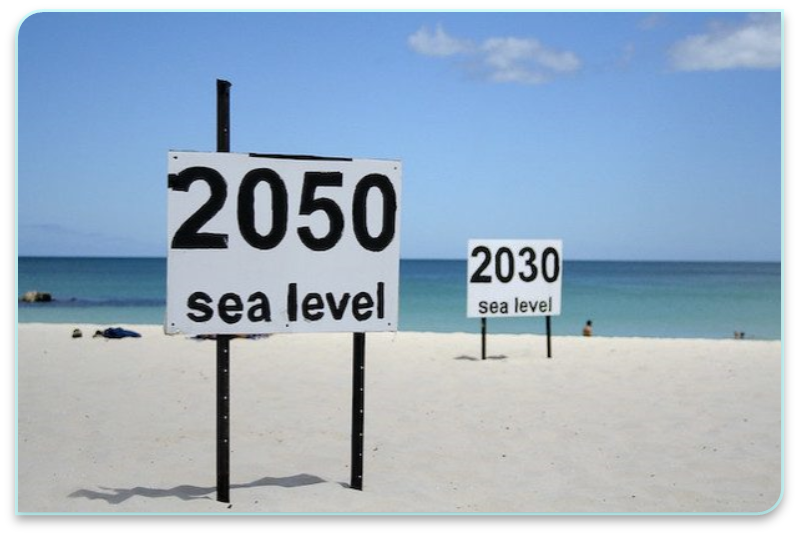

clear all;
warning off;
close all;
clc;

## 1. Analyzing Landmarks and World Maps

The rise in sea levels is one of the most significant consequences of global warming, with countries such as the Netherlands facing the threat of submersion within the next century. The melting of glaciers caused by the increase in carbon dioxide levels and resulting rise in global temperatures is contributing to the worldwide sea level rise. To better understand the factors affecting this increase, we collected and analyzed data, fitting it to a certain function to make predictions for future sea levels. The Root Mean Square Error (RMSE) was used to assess the standard deviation of the prediction errors between predicted and actual values. Additionally, a correlation matrix was used to assess the consistency of the data with each other. This study utilized curve fitting and machine learning methods to better predict and understand the rise in sea levels, which will help us take proactive steps to mitigate its impact.

Annual 2021 Global Climate Report  [2021-2035 by NOAA](https://www.ncei.noaa.gov/access/monitoring/monthly-report/global/202113#:~:text=The%20year%20culminated%20as%20the,ten%20warmest%20years%20on%20record.)

#### Landmarks

worldmap world
load coastlines
whos

  Name             Size            Bytes  Class     Attributes

  coastlat      9865x1             78920  double              
  coastlon      9865x1             78920  double              



[latcells, loncells] = polysplit(coastlat, coastlon);
numel(latcells)

ans = 241

geoshow('landareas.shp', 'FaceColor', 'k')
geoshow('worldlakes.shp', 'FaceColor', 'cyan')
geoshow('worldrivers.shp', 'Color', 'blue')
geoshow('worldcities.shp', 'Marker', '.',...
                           'MarkerEdgeColor', 'magenta')

#### World map

sea_data = fopen('sealeveldata.txt');
SL = textscan(sea_data,'%f %f %f %f %f %f %f %f','headerlines',7);
fclose(sea_data);

sl = [SL{1} SL{2} SL{3} SL{4} SL{5} SL{6} SL{7} SL{8}]';
sl(sl==999)=NaN;
sl = (reshape(sl,[1440 716]))';

lat = repmat(linspace(89.5,-89.5,716)',1,1440);
lon = repmat(linspace(0,360,1440),716,1);


#### **World Map Plot**

figure
ax = worldmap('World');
land = shaperead('landareas', 'UseGeoCoords', true);
geoshow(ax, land, 'FaceColor', 'k');


#### **Plots sea level data   **

[**https://oceanservice.noaa.gov/facts/globalsl.html**](https://oceanservice.noaa.gov/facts/globalsl.html)

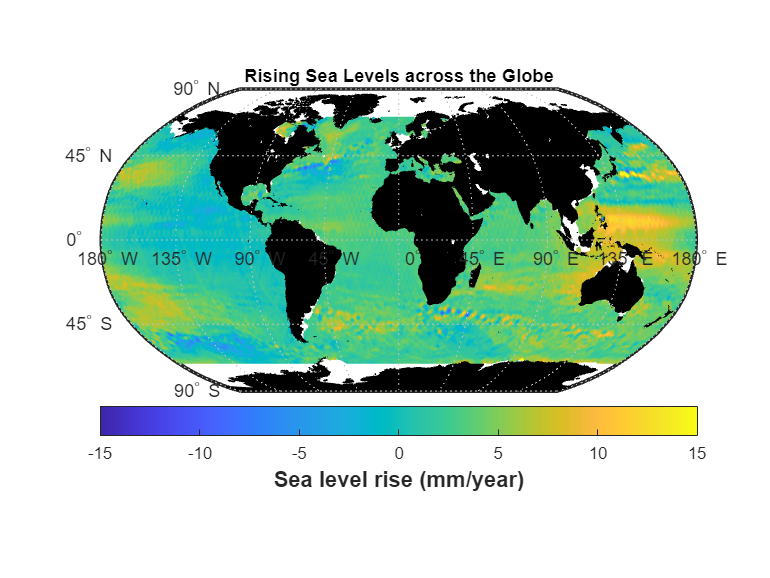

pcolorm(lat,lon,sl)  

cb = colorbar('location','southoutside');
clim([-15 15])
title(ax,'Rising Sea Levels across the Globe','FontWeight','bold','FontSize',10)
xlabel(cb,'Sea level rise (mm/year)','FontWeight','bold','FontSize',12)

## 2. Statistical Test to Evaluate the Relationship Between Variables in a Data Set

#### Correlation Matrix

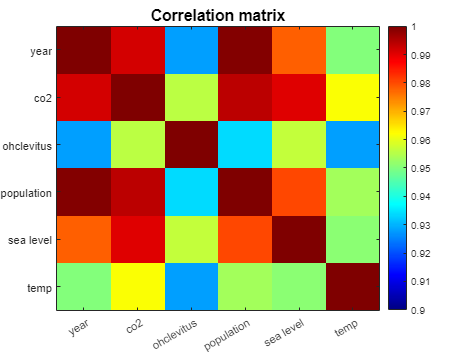

load('final_matrix.mat')
r = corr(finalMatrix);
n = 6;
L = {'year', 'co2','ohclevitus','population','sea level','temp'};
close all;
imagesc(r); % plot the matrix
set(gca, 'XTick', 1:n); % center x-axis ticks on bins
set(gca, 'YTick', 1:n); % center y-axis ticks on bins
set(gca, 'XTickLabel', L); % set x-axis labels
set(gca, 'YTickLabel', L); % set y-axis labels
title('Correlation matrix', 'FontSize', 14); % set title
colormap('jet'); % set the colorscheme
colorbar() ; % Add color bar and make sure the color ranges from 0.9:1
caxis([0.9,1]);

## 3. Curve Fitting

**Import Data**

load("seaRiseMatrix.mat")
temp = temp_data(:,2);
searise = searise_data(:,2);
population = population_data(:,2);
ohclevitus = ohclevitusclimdashseasonal_data(:,2);
co2 = co2_data(:,2);
year = temp_data(:,1);


#### Fit: 'Linear Fitting'

[xData, yData] = prepareCurveData( year, searise );

**Set up fittype and options.**

ft = fittype( {'(sin(x-pi))', '((x-10)^2)', '1'}, 'independent', 'x', 'dependent', 'y', 'coefficients', {'a', 'b', 'c'} ); 

**Fit model to data.**

[fitresult, gof] = fit( xData, yData, ft );

** Plot fit with data.**

figure( 'Name', 'Linear Fitting' );
h = plot( fitresult, xData, yData );
legend( h, 'searise vs. year', 'Linear Fitting', 'Location', 'NorthEast', 'Interpreter', 'none' );

**Label axes**

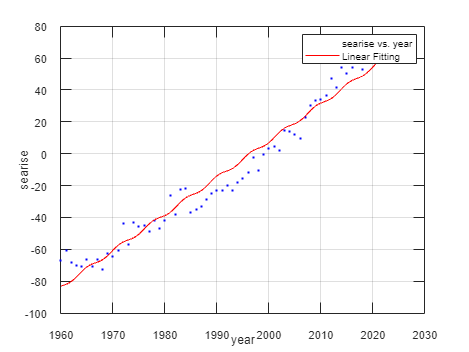

xlabel( 'year', 'Interpreter', 'none' );
ylabel( 'searise', 'Interpreter', 'none' );grid on

#### Fit: 'Polynomial (deg1)'

[xData, yData] = prepareCurveData( year, searise );

**Set up fittype and options**

ft = fittype( 'poly1' );

**Fit model to data**

[fitresult1, gof] = fit( xData, yData, ft );

**Plot fit with data**

figure( 'Name', 'Polynomial(deg1)' );
h = plot( fitresult1, xData, yData );
legend( h, 'searise vs. year', 'Polynomial(deg1)', 'Location', 'NorthEast', 'Interpreter', 'none' );

**Label axes**

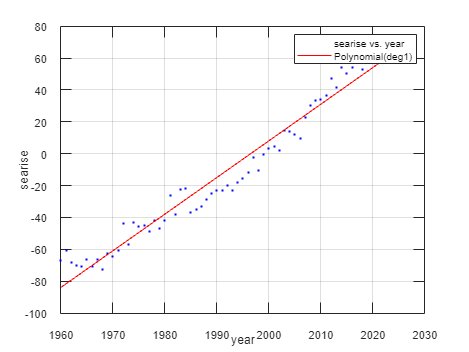

xlabel( 'year', 'Interpreter', 'none' );
ylabel( 'searise', 'Interpreter', 'none' );
grid on

#### Fit: 'Polynomial (deg2)'

[xData, yData] = prepareCurveData( year, searise );

**Set up fittype and options**

ft = fittype( 'poly2' );

**Fit model to data**

[fitresult2, ~] = fit( xData, yData, ft );

**Plot fit with data**

figure( 'Name', 'Polynomial(deg2)' );
h = plot( fitresult2, xData, yData );
legend( h, 'searise vs. year', 'Polynomial(deg2)', 'Location', 'NorthEast', 'Interpreter', 'none' );

**Label axes**

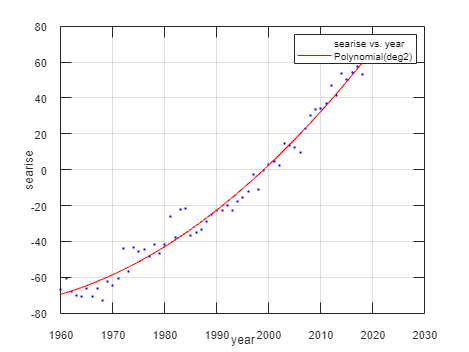

xlabel( 'year', 'Interpreter', 'none' );
ylabel( 'searise', 'Interpreter', 'none' );
grid on

#### Fit: 'Polynomial (deg3)'

[xData, yData] = prepareCurveData( year, searise );

**Set up fittype and options**

ft = fittype( 'poly3' );

**Fit model to data**

[fitresult3, gof] = fit( xData, yData, ft, 'Normalize', 'on' );

**Plot fit with data**

figure( 'Name', 'Polynomial(deg3)' );
h = plot( fitresult3, xData, yData );
legend( h, 'searise vs. year', 'Polynomial(deg3)', 'Location', 'NorthEast', 'Interpreter', 'none' );

**Label axes**

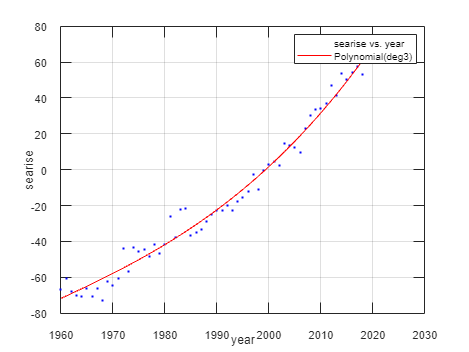

xlabel( 'year', 'Interpreter', 'none' );
ylabel( 'searise', 'Interpreter', 'none' );
grid on

#### Curve Fitting Results

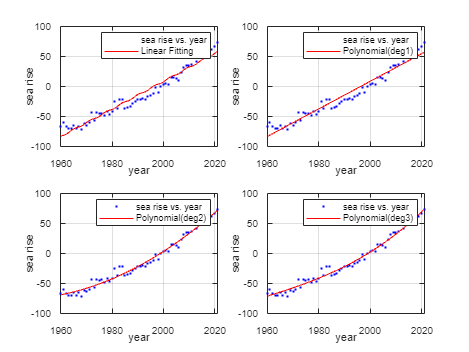

subplot(2,2,1)
h = plot( fitresult, xData, yData );
legend( h, 'sea rise vs. year', 'Linear Fitting', 'Location', 'NorthEast', 'Interpreter', 'none' );
xlabel( 'year', 'Interpreter', 'none' );
ylabel( 'sea rise', 'Interpreter', 'none' );grid on

subplot(2,2,2)
h = plot( fitresult1, xData, yData );
legend( h, 'sea rise vs. year', 'Polynomial(deg1)', 'Location', 'NorthEast', 'Interpreter', 'none' );
xlabel( 'year', 'Interpreter', 'none' );
ylabel( 'sea rise', 'Interpreter', 'none' );
grid on

subplot(2,2,3)
h = plot( fitresult2, xData, yData );
legend( h, 'sea rise vs. year', 'Polynomial(deg2)', 'Location', 'NorthEast', 'Interpreter', 'none' );

xlabel( 'year', 'Interpreter', 'none' );
ylabel( 'sea rise', 'Interpreter', 'none' );
grid on

subplot(2,2,4)
h = plot( fitresult3, xData, yData );
legend( h, 'sea rise vs. year', 'Polynomial(deg3)', 'Location', 'NorthEast', 'Interpreter', 'none' );

xlabel( 'year', 'Interpreter', 'none' );
ylabel( 'sea rise', 'Interpreter', 'none' );
grid on

## 4. Regression Learner

Train regression models to predict data using supervised machine learning [Train Regression Models in Regression Learner App](https://www.mathworks.com/help/stats/machine-learning-in-matlab.html)

The Regression Learner app trains regression models to predict data. Using this app, you can explore your data, select features, specify validation schemes, train models, and assess results. You can perform automated training to search for the best regression model type, including linear regression models, regression trees, Gaussian process regression models, support vector machines, efficiently trained linear regression models, kernel approximation models, ensembles of regression trees, and neural network regression models.

#### Use the Clasification Learner

regressionLearner

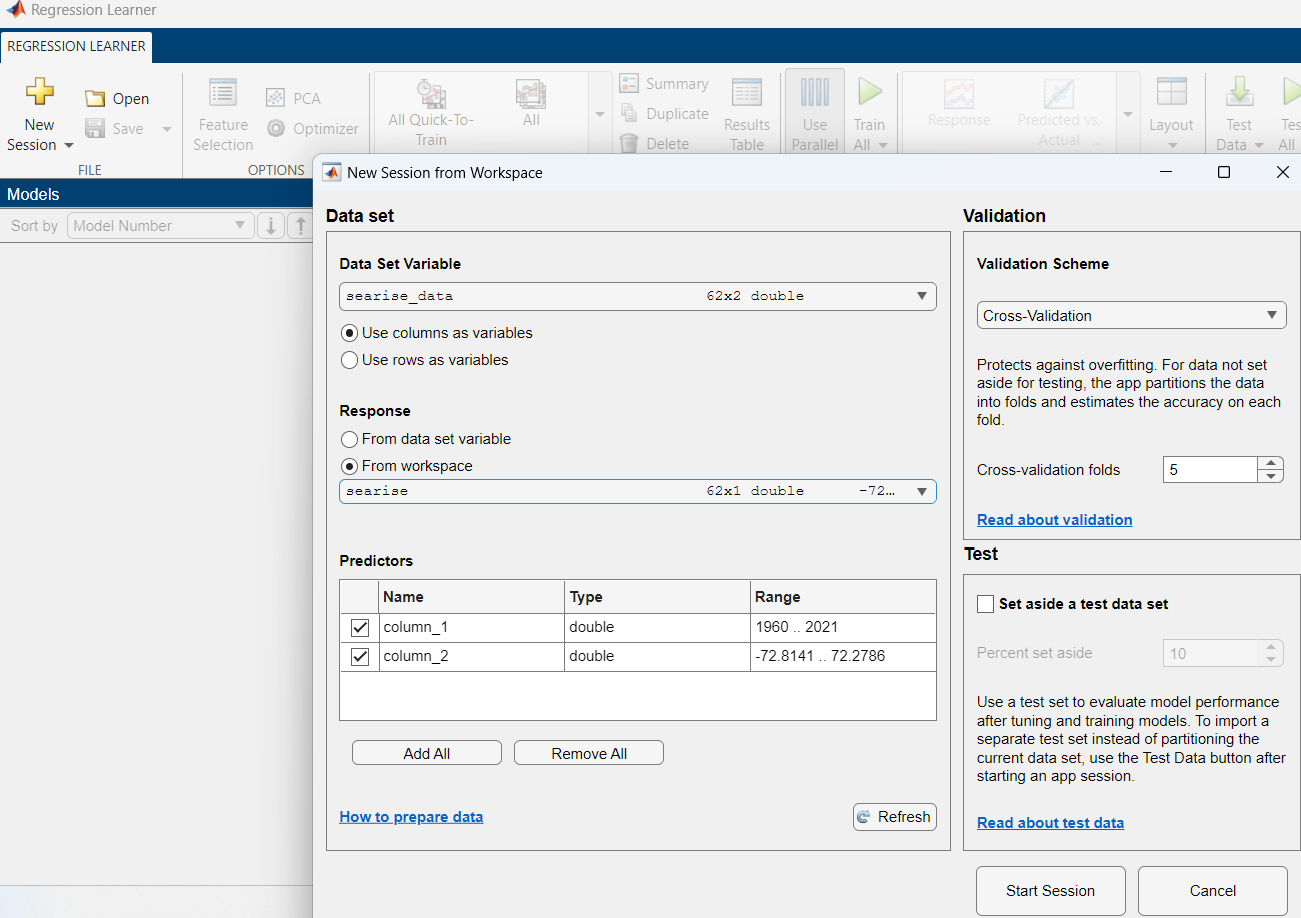

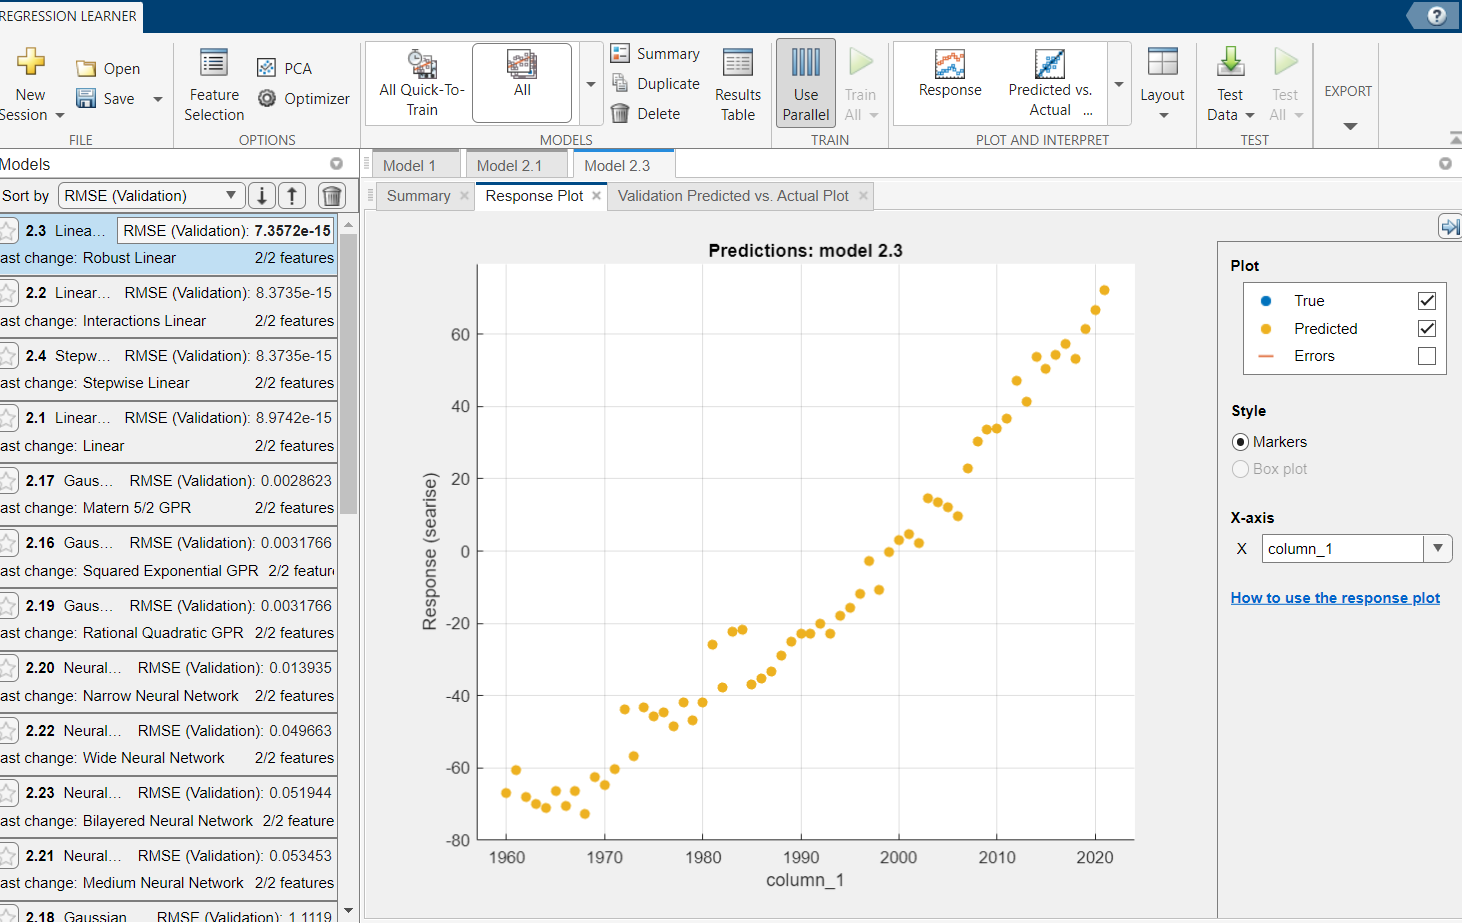

## 5. Sea Level Prediction with Data Reported by  [2021-2035 by NOAA](https://www.ncei.noaa.gov/access/monitoring/monthly-report/global/202113#:~:text=The%20year%20culminated%20as%20the,ten%20warmest%20years%20on%20record.)

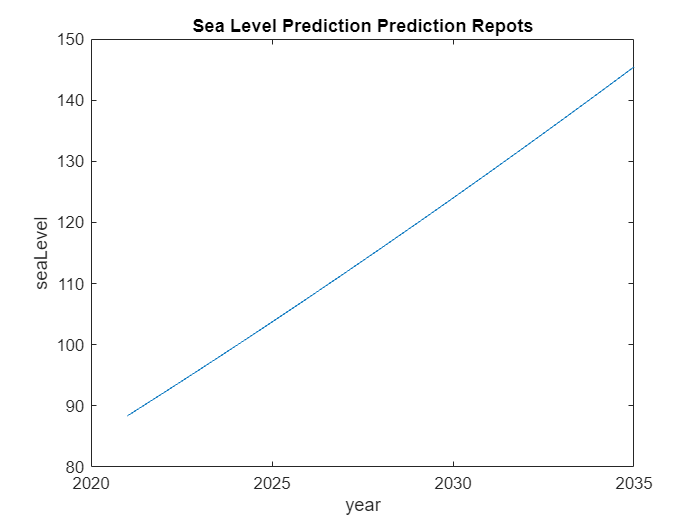

for i = 2021:2035
    yearx = i;
    result(i-2020) = 0.02354*(yearx^2) -91.4*yearx + 8.866e+04 ;
    yearss(i-2020) = i ;
end
figure
plot(yearss,result)
xlabel('year')
ylabel('seaLevel')
title('Sea Level Prediction Repots')

#### Specific Latitude and Longitude Data and Map Visualization

If you have data that is associated with specific geographic locations, use a geographic axes or chart to visualize your data on a map and provide visual context. For example, if you have data that describes the occurrences of tsunamis around the world, plot the data in a geographic axes where a marker indicates the location of each occurrence on a map. [https://www.mathworks.com/help/matlab/creating_plots/plot-in-geographic-coordinates.html](https://www.mathworks.com/help/matlab/creating_plots/plot-in-geographic-coordinates.html)

clear all;
clc;
close all;

**You can use that to visualize specific year. Take user input for the year they want projected sea rise**

yearx = input("Enter the year you would like to learn sea level rise in future: ");

result = 0.02354*(yearx^2) -91.4*yearx + 8.866e+04 ;
result = result - 88;

**36-42 lat ---- 26-45 lon is Turkey's parameters**

lat_start = 36;
lat_end = 42;

lon_start = 26;
lon_end = 45 ;

**Create the map**

geolimits([lat_start lat_end],[lon_start lon_end])
geobasemap streets

**Click any sea to see 'sea level rise'**

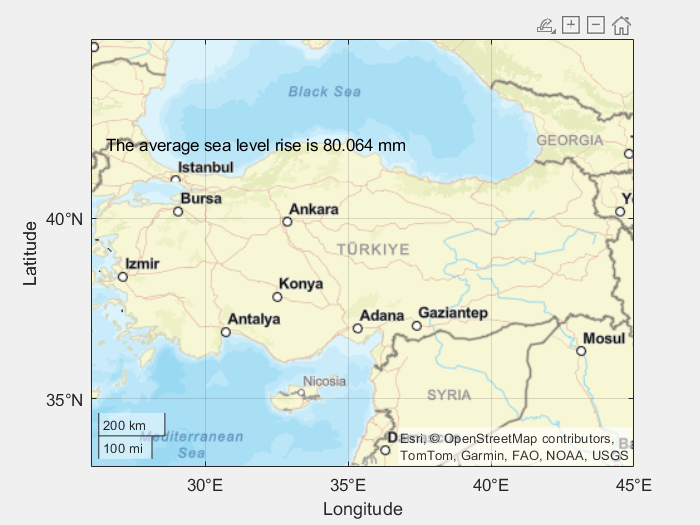

gtextm("The average sea level rise is " + string(result) + " mm")

 It is a work by